# Genetic Algorithim in Tandem with pattern search for a PID controller disregarding implementation cost 

%0 initialisation and set up
    %0.0 plant transfer function     
        s = tf('s');
        G = (2*s^2+1)/(5*s^4+5*s^2+2*s+1);
    %0.1 desired characteristics
        rise_time=0.05

rise_time = 0.0500

        settling_time=0.2

settling_time = 0.2000

        peak_overshoot=10   %in percent copared to steady state value

peak_overshoot = 10

        settling_tolerance=2 %in percent

settling_tolerance = 2

    %0.2 Algorithim paramaters
        weighting_exponent=[1,1,1]      %rise time,settling time, peak overshoot ,

weighting_exponent =      1     1     1


        weighting_proportional=[1,1,1]  %rise time,settling time, peak overshoot 

weighting_proportional =      1     1     1


        weighting=[weighting_proportional;weighting_exponent]

weighting =      1     1     1
     1     1     1


        %if solution is weird then modify mutation factor and other options
        max_generations=18;
        population_size=30;
        elite_proportion=0.05;
        crossover_fraction=0.75;    %%exploitative
        mutation_factor=0.18;       %%eplorative
        num_tests=5               %no. times to run the algorithim 

num_tests = 5

        x_bound=1                %acceptable solution to stop re running more than sum of weighting is reasonable fitness ~>0.5 with weightings of 1 for rise time 

x_bound = 1

        
        % options on the algorithim 
        options=optimoptions(@ga,"MaxGenerations",max_generations,'PopulationSize',population_size,'SelectionFcn',{@selectiontournament,4},'EliteCount',ceil(elite_proportion*population_size),'CrossoverFraction',crossover_fraction,'CrossoverFcn',@crossoverheuristic,'MutationFcn',{@mutationadaptfeasible,mutation_factor});
        x=inf;

%1 algorithim implementation 
    for i=1:num_tests    %for the number of tests
        
        %1.1 execute combined algoritthim
            [K_test,x_test]=PID_Best(G,rise_time,settling_time,peak_overshoot,settling_tolerance,options,weighting);
        %1.2 if new test is better than old overwrite data
            if x_test<x
                K=K_test;
                x=x_test;
            end
        %1.3 if the new test is sufficiently good stop re running
            if x<x_bound
                number_of_iterations=i
                break
            end
    end

Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.


number_of_iterations = 1


%2 testing output solution 
    %2.1 defining solution 
        C=K(1)+K(2)/s+K(3)*s    %controller transfer function 

C =
 
  389.9 s^2 + 700.3 s + 2.995
  ---------------------------
               s
 
Continuous-time transfer function.



        H=feedback(C*G,1)       %closed loop transfer function 

H =
 
      779.7 s^4 + 1401 s^3 + 395.9 s^2 + 700.3 s + 2.995
  ----------------------------------------------------------
  5 s^5 + 779.7 s^4 + 1406 s^3 + 397.9 s^2 + 701.3 s + 2.995
 
Continuous-time transfer function.



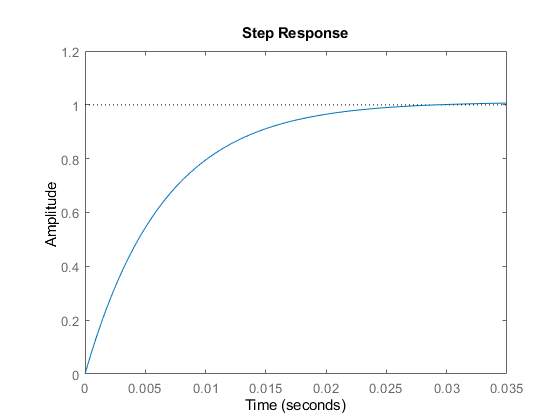

    %2.2 simulation solution 
        step(H)                 %step response

        stepinfo(H)             %step paramaters

ans = struct with fields:
        RiseTime: 0.0136
    SettlingTime: 0.0225
     SettlingMin: 0.9007
     SettlingMax: 1.0098
       Overshoot: 0.9845
      Undershoot: 0
            Peak: 1.0098
        PeakTime: 0.0445


    %2.3 final fitness value
        fitness=pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K)

fitness = 0

        function [K,x]=PID_Best(G,rise_time,settling_time,peak_overshoot,settling_tolerance,options,weighting)

        fitness_function=@(K)pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K);

[K,~] = ga(fitness_function,3,-1*eye(3),zeros(3,1),[],[],[],[],[],[],options);

[K,x] = patternsearch(fitness_function,K,-1*eye(3),-1e-6*ones(3,1));

end

function fitness=pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K)
    s=tf('s');
    if ~all(K)
        fitness=inf;
    else
        C=K(1)+K(2)/s+K(3)*s;
        H=feedback(C*G,1);
        [Y,T]=step(H,[0:1E-4:20]);
        fitness=eval_fitness(Y,T,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting);
        
        if isnan(fitness)
            fitness=inf;
        end
    end
    
end
        
function fitness=eval_fitness(Y,T,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting)
        fit1=weighting(1,3)*fit_segment(Y,T,0,rise_time,0,1+peak_overshoot/100)^weighting(2,3);
        fit2=weighting(1,2)*fit_segment(Y,T,rise_time,settling_time,0.9,1+peak_overshoot/100)^weighting(2,1);
        fit3=weighting(1,2)*fit_segment(Y,T,settling_time,T(end),1-settling_tolerance/100,1+settling_tolerance/100)^weighting(2,2);
        fitness=fit1+fit2+fit3;
    end
    
    function fit=fit_segment(Y,T,t_min,t_max,y_min,y_max)
        indexes=(T>t_min & T<=t_max);
        y=Y(indexes);
        y=(y-y_max).*heaviside(y-y_max)+(y_min-y).*heaviside(y_min-y);
        fit=trapz(y);
    end
    
